# Practice Problem Solutions

### Convolution: Basics

The code below generates two signals. Study this code and perform the tasks below to complete this section.

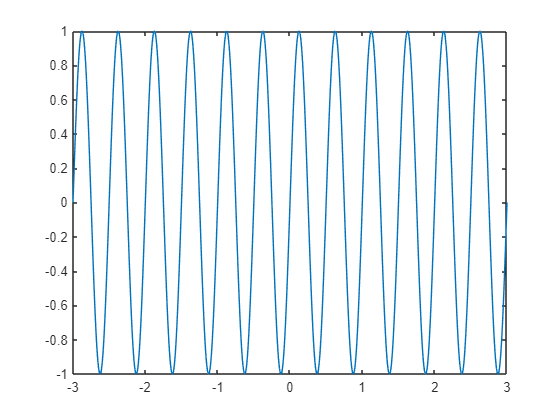

fs = 10000;                   % Sampling frequency, increase this to increase number of samples in the signals

% Generate a sine wave
t = -3 : 1/fs : 3;
u = sin(4*pi*t);
plot(t, u)

M = length(u);
fprintf("Length of u: M = "+ M)

Length of u: M = 60001

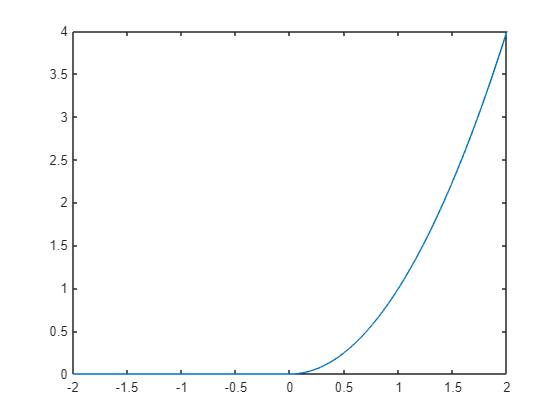


% Generate a parabolic signal from a unit step
t2 = -2 : 1/fs : 2;
unitstep = (t2 >= 0);
v = t2.^2 .* unitstep; 
plot(t2, v)

N = length(v);
fprintf("Length of v: N = "+ N)

Length of v: N = 40001

**Task:** Compute the full-length output of linear convolution of $u\left(t_1 \right)$ and $v\left(t_2 \right)$ and plot the result.

w = conv(u, v, 'full')./fs;    

*Note**: To get an approximate for the continuous convolution output using discrete signals, you must normalize (divide) the convolution output by *`fs`*.*

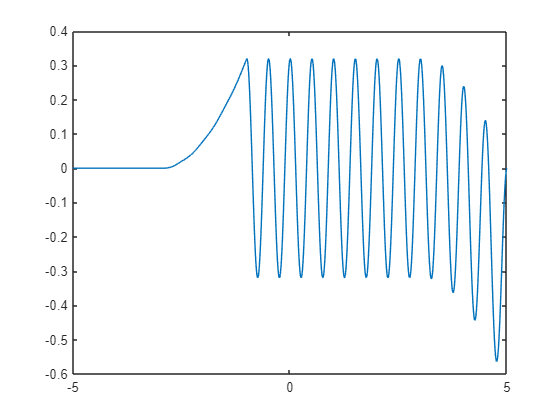

% Plot the output of the convolution by replacing the code in the text box.
T = -5: 1/fs: 5;           
plot(T, w);

**Task:** Compute circular convolution of `u` and v using `fft` and `ifft` to get the linear convolution equivalent output. Plot the result.

%Zero-pad the signal to make them the required lengths.
upad = [u, zeros(1, N-1)];      % pad u
vpad = [v, zeros(1, M-1)];             % pad v

% Use fft and ifft to compute circular convolution output.
wCirc = ifft(fft(upad).* fft(vpad))./fs; 

% Compute the length of output. Is it the expected length?
length(wCirc) 

ans = 100001

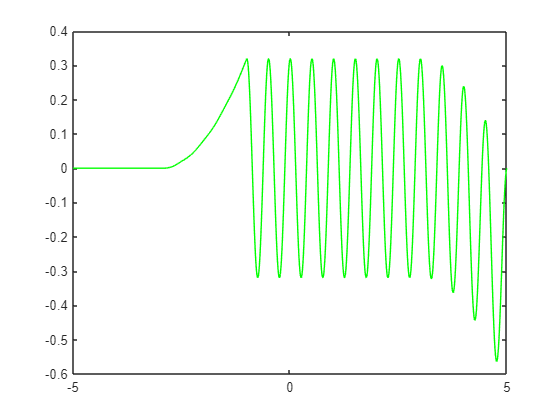


% Plot the output of the convolution against the time vector T. Uncomment
% the next line to enter code.
plot(T, wCirc, "g") 

### Convolution and LTI Systems

fs = 1000;                   % Sampling frequency
n = -5 : 1/fs : 5;           % Discretized time 

% Get the impulse response of an unknown LTI System using the helper function getImpulseResponse
h = getImpulseResponse(n, fs);

Compute the output for an input sequence `x.`

x = exp(n);
y = conv(h,x,"same");

Plot the input x and output `y`.

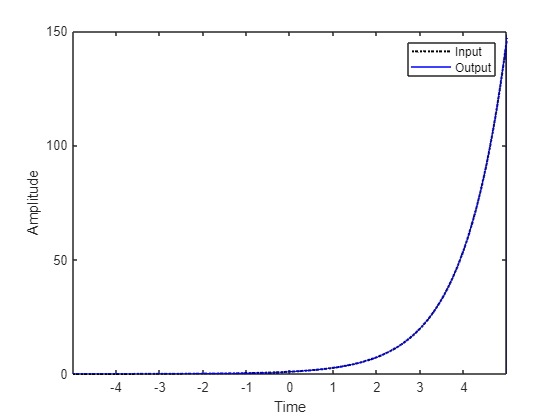

figure;
plot(n,x,"k:", "LineWidth", 1.5);
hold on
plot(n,y,"b")
hold off
xlim([-4.99 4.99])
xlabel("Time");
ylabel("Amplitude")
legend("Input", "Output")

- Change `x` to different signals using the dropdown.

- Based on your observations, what operation do you think this LTI system is performing on the inputs? *** It is a first-order derivative.***

- Change the *x*-axis limits to `[-5 5]`. What do you notice? (*Hint*: Change `x` to `exp(n)`)  ***There is a sudden change in the last element of the output.***

- Examine the last two values of `y` when` x = exp(n)`. If you notice something strange near the end of the signal, can you explain what might be causing this? ***The derivative of ***`exp(n)`***, ***`y`*** is expected to be the same as ***`x. `***However***`,`*** last element of***` y `***is approximately***` -148.413 `***instead of the expected***` 148.413. `***This is because the definition of the derivative breaks down at the border. This is occurring only at the last element because our system approximates the derivative using the forward difference method. See the function ***`getImpulseResponse`*** at the bottom of this script to understand the system.***

### Convolution and Filtering

Let us compute 2-D linear convolution via [fft2](https://www.mathworks.com/help/matlab/ref/fft2.html) to visualize the process of filtering in the frequency domain and to understand the notion of frequency in images. 

Perform the tasks as directed to complete this code section.

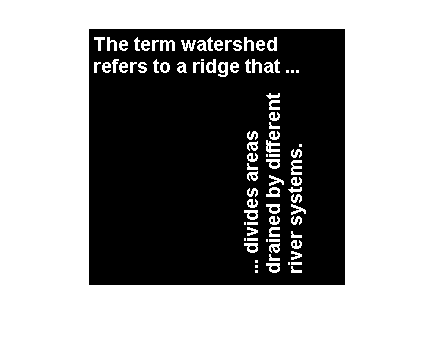

% Import a grayscale image and display it.
I = imread('text.png');

% Convert images to grayscale uint8 datatype before further processing. 
I = im2gray(im2uint8(I));
imshow(I)


% Create some filter kernels to test. You can add your own to the list.
W = 5;
h1 = ones(W)./W.^2;

h2 = [1 0 -1; 
     2 0 -2; 
     1 0 -1];

h3 = [1 2 1; 
     0 0 0; 
    -1 -2 -1];

h = h2

h =      1     0    -1
     2     0    -2
     1     0    -1


Compute the size for full linear convolution based on the size of the image and the filter kernel.

% Get the sizes of the image and filter kernel.
[MI, NI] = size(I);
[Mh, Nh] = size(h);

% Compute size of full convolution output for each dimension.
m        = MI+Mh+1;         % rows
n        = NI+Nh+1;         % columns

Use [`fft2`](https://www.mathworks.com/help/matlab/ref/fft2.html) to compute 2-D Fourier transform of image `I,` with size of `m` rows and `n` columns. We will use [`imagesc`](https://www.mathworks.com/help/matlab/ref/imagesc.html) function to visualize the 2-D FFT output with scaled colors.

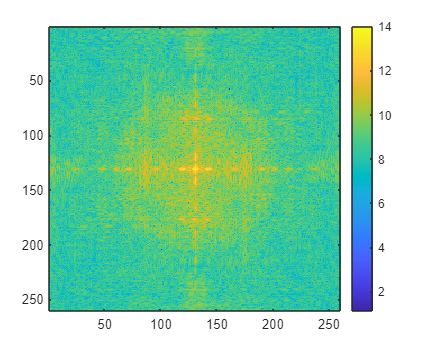

% Compute FFT of grayscale image.
F1 = fft2(I,m,n); 
% Display FFT output using a colormap and log scale for better visualization.
imagesc(fftshift(log(1+abs(F1))))
colorbar

**Task: **Use [`fft2`](https://www.mathworks.com/help/matlab/ref/fft2.html) to compute 2-D Fourier transform of filter `h,` with size of `m` rows and `n` columns. 

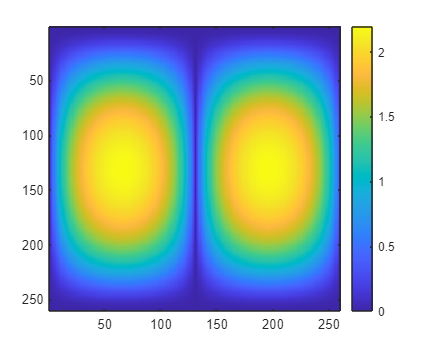

% Compute FFT of filter kernel.
F2 = fft2(h,m,n);
% Display FFT output using a colormap and log scale for better visualization.
imagesc(fftshift(log(1+abs(F2))))
colorbar

**Task: **Multiply `F1` and `F2` element-wise.

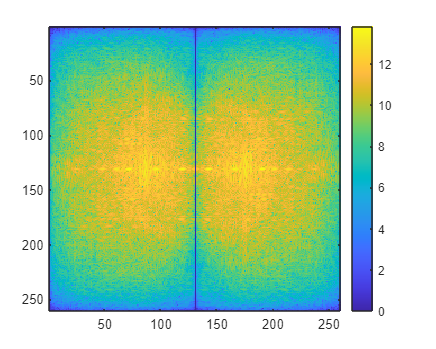

% Convolution in spatial domain is multiplication in frequency domain.
F = F1.*F2;
% Display FFT output using a colormap and log scale for better
% visualization.
imagesc(fftshift(log(1+abs(F))))
colorbar

**Task:** Compute and inverse Fourier transform of the product `F` using [ifft2](https://www.mathworks.com/help/matlab/ref/ifft2.html). This will give us the filtered image. 

% Compute inverse FFT of the product.
Ifilt = ifft2(F);

Trim the image down to the right size to achieve the equivalent of linear convolution. Convert the image to unsigned 8-bit integer and view the output.

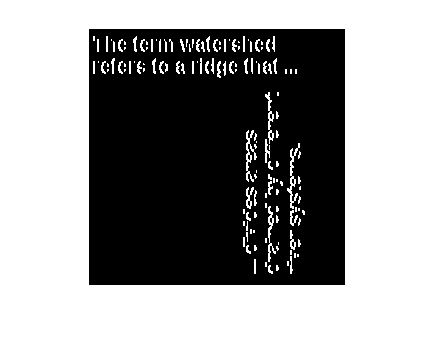

Ifilt = Ifilt(ceil(Mh/2):end-(ceil(Mh/2)+1), ceil(Nh/2):end-(ceil(Nh/2)+1));
Ifilt = uint8(real(Ifilt)); 
imshow(Ifilt)

Perform the equivalent linear spatial convolution of `I` and `h` using [imfilter](https://www.mathworks.com/help/images/ref/imfilter.html) with the `"conv"` option. Verify if the results match.

Ifilt2 = imfilter(I, h, "conv");
imshow(Ifilt2)

**Task: **Try using different filter kernels from the dropdown at the top of this section and analyze the results.

**Function for "Convolution and LTI Systems" further practice.**

function h = getImpulseResponse(n,fs)

D = n == 0;      % Impulse signal
D(end+1) = 0;    
h = diff(D)*fs;  % Forward difference operation

end

